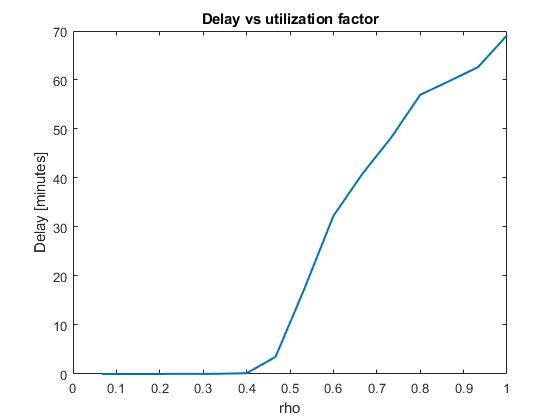

clear;
close all;
avgDelay = [];

%lambda=1;

for lambda=0.1:0.1:1.5
    max_user_delayed = 10000;
    time = 0;
    users = 0;
    server = 0;
    area_users = 0;
    area_server = 0;
    n_delayed = 0;
    delay = 0;
    service_time = inf;
    time_since_le = 0;
    time_le = 0;
    time_arrival = [];
    next_arrival = time+exprnd(1/lambda);
    while n_delayed < max_user_delayed
        if next_arrival==service_time
            break;
        end
        [min_val,min_idx] = min([next_arrival,service_time]);
        time = min_val;
        time_since_le = time-time_le;
        time_le = time;
        area_users = area_users + users*time_since_le;
        area_server = area_server + server*time_since_le;
        
        if min_idx == 1 %arrival event
            next_arrival = time+exprnd(1/lambda); %schedule next arrival
            if server == 1 %server busy
                users = users + 1; %enqueue the arriving user
                time_arrival(users) = time;
            else %server idle
                server = 1;
                n_delayed = n_delayed + 1;
                %schedule departure
                if rand()<0.5
                    service_time = time+1;
                else
                    service_time = time+2;
                end
%                 service_time=time+exprnd(1/2);
            end
        else %departure event
            if users == 0
                server = 0;
                service_time = inf;
            else
                users = users - 1;
                delay = delay + time - time_arrival(1);
                n_delayed = n_delayed + 1;
                %schedule departure
                if rand()<0.5
                    service_time = time+1;
                else
                    service_time = time+2;
                end
%                 service_time=time+exprnd(1/2);
                time_arrival(1)=[];
            end
        end
    end
    avgDelay(end+1) = delay/n_delayed;
end

lvec = 0.1:0.1:1.5;
rhovec = lvec./1.5; % 0.5*1+0.5*2 = 1.5 is the mean service time
plot(rhovec,avgDelay./60,'LineWidth',1.5);
title('Delay vs utilization factor');
xlabel('rho');
ylabel('Delay [minutes]');

% avgDelay = delay/n_delayed
% avgQueued = area_users/time
% avgServerUtilization = area_server/time